**PID Modeling Tuning Rules**

**Learning Objectives: **

**1) Understand how to use model tuning rules to determine PID controller parameters.**

**2) Implement model tuning rules to a PID controller and observe the response. **

In this example, we will model a three-tank system, determine the model tuning, and implement a PID controller for the system. 

The transfer function for a three-tank system can be given in the following form: 


$$G\left(s\right)=\frac{6}{\left(2s+1\right)\left(4s+1\right)\left(6s+1\right)}=\frac{6}{\;48s^3 +44s^2 +12s+1}$$


The model tuning parameters are given as a function of $K,\tau ,\textrm{and}\;\alpha \;$from the first-order plus time delay (FOPTD model). Consequently, we must develop an approximation of the three-tank system. Use the matlab code below to determine appropriate FOPTD parameters. 

G = tf([6], [48 44 12 1]);

K = 6

K = 6

Tau = 6

Tau = 6

Delay = 5

Delay = 5

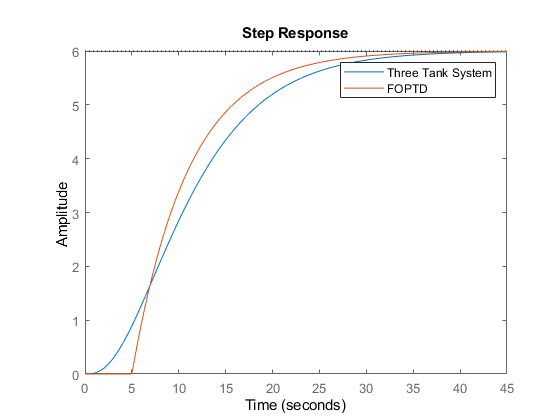


FOPTD = tf([K],[Tau 1],'InputDelay',Delay);
figure 
hold on
step(G)
step(FOPTD)
legend('Three Tank System','FOPTD')

There are multiple tuning rules as functions of $K,\tau ,\textrm{and}\;\alpha \;$that we have generated above. In the module below, the code takes the parameters derived and implements them into the model tuning rules. 

For example, the Ziegler-Nichols tuning rules provide the following equations: 

$K_c =\frac{1\ldotp 2}{K}\left(\frac{\tau }{\alpha \;}\right)$; $\tau_i =2\alpha \;$; $\tau_d =0\ldotp 5\alpha \;$

Please refer to the lecture notes and the textbook (Chapter 15.4.2 - Pages 535 to 541)

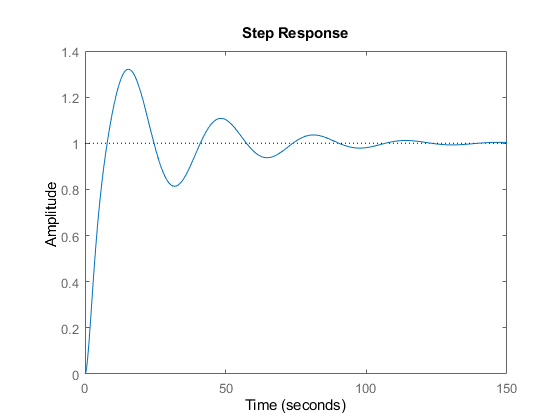

figure
G = tf([6],[48 44 12 1]);
PID_Parameters = [(Tau/(K*Delay))*(4/3 + 0.25*(Delay/(4*Tau))) Delay*((32 + 6*Delay/Tau)/(13 + 8*Delay/Tau)) Delay*(4/(11+2*Delay/Tau))];
Kp = PID_Parameters(1);
Tau_i = PID_Parameters(2);
Tau_d = PID_Parameters(3);

C = pid(Kp, 1/Tau_i, Tau_d);
sys = feedback(C*G,1);
step(sys)
hold on